# NUM on the MITgcm and UVic transport matrices

Three simulated years of `setupNUMmodel` on each of the two transport matrix configurations, started from the same initial conditions, compared.

The commit and date this was last run for are printed below, so the stored output can be traced back to the state of the code that produced it.

% This notebook lives in Notebooks/, but inputRead and loadNUMmodelLibrary
% resolve ../input/input.yaml against the working directory, so move into
% matlab/ before anything else is called.
nbDir = fileparts(mfilename('fullpath'));
if isempty(nbDir), nbDir = pwd; end
root = fileparts(nbDir);
addpath(fullfile(root, 'matlab'));
cd(fullfile(root, 'matlab'));

[okC, commit] = system(sprintf('git -C "%s" rev-parse --short HEAD', root));
[okB, branch] = system(sprintf('git -C "%s" rev-parse --abbrev-ref HEAD', root));
[~,   dirty]  = system(sprintf('git -C "%s" status --porcelain --untracked-files=no', root));
if okC == 0 && okB == 0
    if isempty(strtrim(dirty)), state = ''; else, state = ', working tree modified'; end
    fprintf('Run for commit %s on branch %s%s\n', strtrim(commit), strtrim(branch), state);
else
    fprintf('Run from %s (git commit unavailable)\n', root);
end

Run for commit cd003fc on branch UVicTM, working tree modified


fprintf('Run on %s\n', string(datetime('now','Format','yyyy-MM-dd HH:mm')));

Run on 2026-09-30 17:39


## What is being compared

**What "the same initial conditions" means here.** The two grids are different shapes, so an identical state vector is not possible. Both runs take `simulateGlobal`'s default: nitrogen and silicate from each grid's own `N0`/|Si0| field, and DOC and every biomass class uniform from `p.u0`. So the biology starts identical everywhere, and the nutrients start from the same physical field mapped onto each grid.

**What differs besides the grid.** UVic is run with the transport step of a third of a day that its matrices are built for, and Euler steps of a twelfth, against MITgcm's half day and a tenth. That is deliberate - see the comments in `parametersGlobal` - but it does mean a difference here is grid **and** timestep, not grid alone.

All paired figures below share one colour scale and one set of axis limits, so the panels can be read against each other directly.

## Load, or run

Each run is three simulated years and takes several minutes. Both are cached as `.mat` files in `Notebooks/cache`, so every figure below can be regenerated without running the model again. That directory is git-ignored: the caches run to about a gigabyte and are output, not source. Delete it to force a re-run.

nYears = 3;

dirCache = fullfile(nbDir, 'cache');
if ~isfolder(dirCache), mkdir(dirCache); end

fileM = fullfile(dirCache, 'sim_mitgcm.mat');
fileU = fullfile(dirCache, 'sim_uvic.mat');

if isfile(fileM)
    load(fileM, 'sim'); simM = sim;
else
    p = setupNUMmodel(bParallel=true);
    p = parametersGlobal(p, 1);
    p.tEnd = nYears*365; p.tSave = 365/12;
    simM = simulateGlobal(p);
    sim = simM; save(fileM, 'sim', '-v7.3');
end

if isfile(fileU)
    load(fileU, 'sim'); simU = sim;
else
    p = setupNUMmodel(bParallel=true);
    p = parametersGlobal(p, 3);
    p.tEnd = nYears*365; p.tSave = 365/12;
    simU = simulateGlobal(p);
    sim = simU; save(fileU, 'sim', '-v7.3');
end
clear sim

nameM = simM.p.TMname;
nameU = simU.p.TMname;
% panelGlobal puts its title through the TeX interpreter, where a bare
% underscore subscripts the next character
texM = strrep(nameM, '_', '\_');
texU = strrep(nameU, '_', '\_');

% The maps, the sections and the spectrum below average over the *final*
% simulated year rather than the whole run. Averaging all three would mix the
% settled state with the spin-up away from the uniform initial biomass, which
% is visible in the time series in the next two sections.
iM = finalYear(simM);
iU = finalYear(simU);
fprintf('averaging window: days %.0f-%.0f of %d\n', ...
    min(simM.t(iM)), max(simM.t(iM)), nYears*365);

averaging window: days 730-1095 of 1095


## The two configurations

Sizes, timesteps and whether nitrogen was conserved over the three years.

[~, dNdtM] = checkConservation(simM, false);
[~, dNdtU] = checkConservation(simU, false);

tbl = table( ...
    {nameM; nameU}, ...
    [numel(simM.x); numel(simU.x)], ...
    [numel(simM.y); numel(simU.y)], ...
    [numel(simM.z); numel(simU.z)], ...
    [simM.p.dtTransport; simU.p.dtTransport], ...
    [simM.p.dt; simU.p.dt], ...
    [dNdtM; dNdtU], ...
    'VariableNames', {'matrices','nLon','nLat','nDepth','dtTransport','dt','relNbalance'});
disp(tbl)

          matrices           nLon    nLat    nDepth    dtTransport       dt       relNbalance
    _____________________    ____    ____    ______    ___________    ________    ___________

    {'MITgcm_2.8deg'    }    128      64       15            0.5           0.1    3.7824e-07 
    {'UVicOSUpicdefault'}    100     100       19        0.33333      0.083333    6.6321e-13 



## Total nitrogen through the run

`calcGlobalN` sums over cells and returns grammes, so this is one of the few quantities that can be compared between the grids without qualification. A flat line is the conservation check; the level is set by the nutrient field each grid was initialised with.

**This is the caveat that matters for everything below.** "The same initial conditions" is weaker than it sounds: the two grids are initialised from the same physical nutrient field, but mapping it onto different grids does not preserve the total, and UVic ends up holding about 15% more nitrogen than MITgcm to begin with. So the two runs are not competing on equal stock, and a biomass difference of that order should not be read as an effect of the circulation. The curves are plotted relative to each run's own start for that reason; the absolute values are printed below.

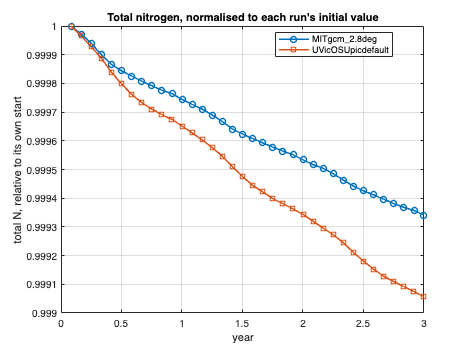

Nm = calcGlobalN(simM);
Nu = calcGlobalN(simU);

figure
plot(simM.t/365, Nm/Nm(1), '-o', simU.t/365, Nu/Nu(1), '-s', 'LineWidth', 1.5)
xlabel('year'); ylabel('total N, relative to its own start')
legend(nameM, nameU, 'Interpreter','none', 'Location','best')
title('Total nitrogen, normalised to each run''s initial value')
grid on


fprintf('initial total N: %s %.3e g, %s %.3e g  (ratio %.3f)\n', ...
    nameM, Nm(1), nameU, Nu(1), Nu(1)/Nm(1));

initial total N: MITgcm_2.8deg 5.011e+11 g, UVicOSUpicdefault 5.788e+11 g  (ratio 1.155)


## Global mean biomass through the run

Depth-integrated with `calcIntegrateGlobal` to g/m^2, then averaged over the globe with cos(latitude) weights so the two grids can be put on one axis. Three years is long enough to show the initial transient away from the uniform starting biomass separately from the seasonal cycle that follows it, which is the reason for running more than one.

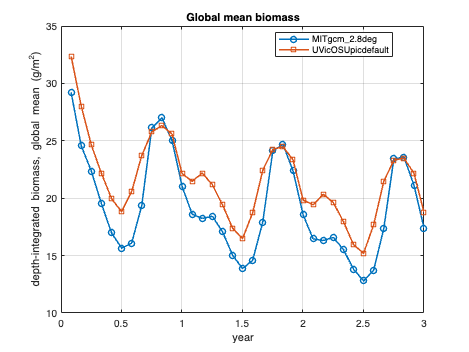

bM = globalMeanSeries(simM, simM.B);
bU = globalMeanSeries(simU, simU.B);

figure
plot(simM.t/365, bM, '-o', simU.t/365, bU, '-s', 'LineWidth', 1.5)
xlabel('year'); ylabel('depth-integrated biomass, global mean (g/m^2)')
legend(nameM, nameU, 'Interpreter','none', 'Location','best')
title('Global mean biomass')
grid on


fprintf('final-year mean biomass: %s %.3f g/m^2, %s %.3f g/m^2  (ratio %.3f)\n', ...
    nameM, mean(bM(iM)), nameU, mean(bU(iU)), mean(bU(iU))/mean(bM(iM)));

final-year mean biomass: MITgcm_2.8deg 17.429 g/m^2, UVicOSUpicdefault 19.634 g/m^2  (ratio 1.127)


fprintf('first-year mean biomass: %s %.3f g/m^2, %s %.3f g/m^2\n', ...
    nameM, mean(bM(simM.t <= 365)), nameU, mean(bU(simU.t <= 365)));

first-year mean biomass: MITgcm_2.8deg 21.987 g/m^2, UVicOSUpicdefault 24.359 g/m^2


## Community Sheldon spectrum

`calcCommunitySpectrum` builds the community spectrum across all groups as defined in Andersen and Visser (2023), Box V. It is given the globally averaged biomass concentration of each size class, so the two grids are reduced the same way before the spectrum is formed. Both runs use the same `setupNUMmodel`, so the underlying size grid is identical.

`calcCommunitySpectrum` indexes the biomass matrix by row using `sim.t`, and averages over the second half of the run when no time index is given. Here it is given the final-year indices explicitly, so the spectrum covers the same window as the maps below rather than a window of the function's choosing.

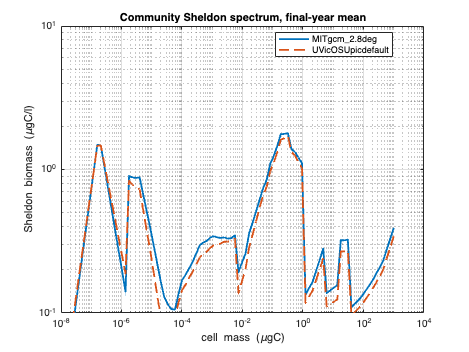

[mcM, BSheldonM] = calcCommunitySpectrum(meanConcByClass(simM), simM, find(iM));
[mcU, BSheldonU] = calcCommunitySpectrum(meanConcByClass(simU), simU, find(iU));

figure
loglog(mcM, BSheldonM, '-', mcU, BSheldonU, '--', 'LineWidth', 1.8)
xlabel('cell mass (\mugC)'); ylabel('Sheldon biomass (\mugC/l)')
legend(nameM, nameU, 'Interpreter','none', 'Location','best')
title('Community Sheldon spectrum, final-year mean')
ylim([0.1 10])
grid on

## Depth-integrated biomass

Mean over the final simulated year, on a shared colour scale. The grids are different resolutions, so the panels are shown separately rather than differenced.

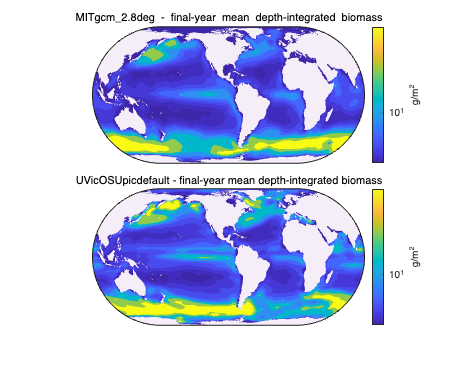

aM = mapField(simM, iM);
aU = mapField(simU, iU);
levels = sharedLevels(aM, aU);

figure('Position',[100 100 900 700])
tiledlayout(2,1, 'TileSpacing','compact')

nexttile
panelGlobal(simM.x, simM.y, aM, levels, sProjection='eckert4', ...
    sTitle=sprintf('%s - final-year mean depth-integrated biomass', texM), ...
    sUnits='g/m^2');
set(gca, 'colorscale', 'log')

nexttile
panelGlobal(simU.x, simU.y, aU, levels, sProjection='eckert4', ...
    sTitle=sprintf('%s - final-year mean depth-integrated biomass', texU), ...
    sUnits='g/m^2');
set(gca, 'colorscale', 'log')

## Zonal mean sections

Biomass averaged over longitude and over the final year, latitude against depth, on a shared colour scale and a shared depth axis, so the extra four layers of the UVic grid read as depth range rather than as a change of scale.

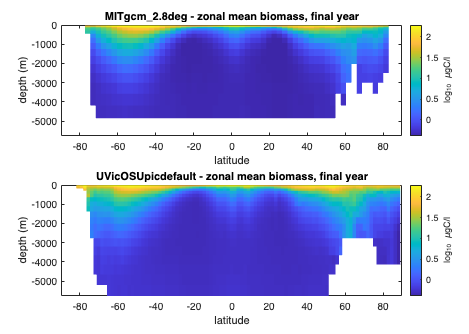

zM = zonalField(simM, iM);
zU = zonalField(simU, iU);
clim2 = sharedLimits(zM, zU);
depthMax = max(max(simM.z), max(simU.z));

figure('Position',[100 100 900 640])
tiledlayout(2,1, 'TileSpacing','compact')

nexttile
drawZonal(simM, zM, clim2, depthMax)
title(sprintf('%s - zonal mean biomass, final year', nameM), 'Interpreter','none')

nexttile
drawZonal(simU, zU, clim2, depthMax)
title(sprintf('%s - zonal mean biomass, final year', nameU), 'Interpreter','none')

## ECCO: a check rather than a third run

`MITgcm_ECCO` is the 1 degree configuration - 682604 wet boxes against MITgcm_2.8deg's 52749 - so three years of it costs far more than the two runs above and would hold tens of GB of output. What is worth establishing here is that the configuration works end to end: that the matrices load, that the `parday` light field for this grid is found and used, and that nitrogen is conserved. So this section runs 30 days rather than three years.

ECCO already ships a `parday.mat` on its own grid, which is why `bUse_parday_light` is true for it in `parametersGlobal`. That existing file is used as it stands rather than rebuilt. The check below confirms it is actually picked up and produces a sensible light field, rather than the run silently falling back to computed light.

fileE = fullfile(dirCache, 'sim_ecco30.mat');
if isfile(fileE)
    load(fileE, 'sim'); simE = sim; clear sim
else
    p = setupNUMmodel(bParallel=true);
    p = parametersGlobal(p, 2);
    p.tEnd = 30; p.tSave = 10;
    simE = simulateGlobal(p);
    sim = simE; save(fileE, 'sim', '-v7.3'); clear sim
end

[~, dNdtE] = checkConservation(simE, false);
nWet = sum(~isnan(reshape(simE.N(1,:,:,:), 1, [])));
fprintf('ECCO grid            : %d x %d x %d  (%d wet boxes)\n', ...
    numel(simE.x), numel(simE.y), numel(simE.z), nWet);

ECCO grid            : 360 x 160 x 23  (682604 wet boxes)


fprintf('parday light in use  : %d  (%s)\n', simE.p.bUse_parday_light, ...
    ternary(isfile(simE.p.pathPARday), 'file present', 'FILE MISSING'));

parday light in use  : 1  (file present)


fprintf('max light in field   : %.1f  (0 would mean the light field is dead)\n', ...
    max(simE.L(:)));

max light in field   : 442.7  (0 would mean the light field is dead)


fprintf('relative N balance   : %+.2e 1/yr\n', dNdtE);

relative N balance   : +3.32e-07 1/yr


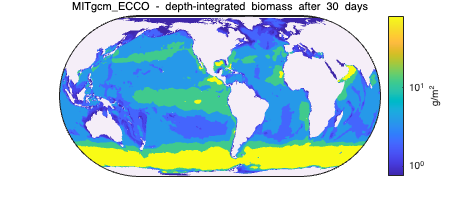


aE = mapField(simE);
figure('Position',[100 100 900 380])
panelGlobal(simE.x, simE.y, aE, sharedLevels(aE, aE), sProjection='eckert4', ...
    sTitle=sprintf('%s - depth-integrated biomass after 30 days', ...
                   strrep(simE.p.TMname,'_','\_')), ...
    sUnits='g/m^2');
set(gca, 'colorscale', 'log')

## Helper functions

function idx = finalYear(sim)
    % Logical index of the saves lying in the last 365 days of the run. The
    % tolerance keeps the save that falls exactly on the boundary out, so the
    % window holds one year of saves and not one more.
    idx = sim.t(:)' > max(sim.t) - 365 + 1e-6;
end

function s = ternary(c, a, b)
    if c, s = a; else, s = b; end
end

function w = latWeights(sim)
    % cos(latitude), so a global mean is not dominated by the poles
    w = cos(deg2rad(sim.y(:)));
end

function m = weightedNanMean(a, w)
    % a is [x, y], w is the latitude weight for each y. Land is NaN or zero.
    a(a == 0) = NaN;
    W = repmat(w(:)', size(a,1), 1);
    valid = ~isnan(a);
    m = sum(a(valid).*W(valid)) / sum(W(valid));
end

function s = globalMeanSeries(sim, field)
    % Depth-integrate to g/m^2, then area-weighted global mean, per save
    Bint = calcIntegrateGlobal(sim, field);        % [time, x, y]
    w = latWeights(sim);
    s = zeros(size(Bint,1),1);
    for i = 1:size(Bint,1)
        s(i) = weightedNanMean(squeeze(Bint(i,:,:)), w);
    end
end

function B = meanConcByClass(sim)
    % Globally averaged concentration of each size class, as [time, class].
    % cos(latitude) weighted over the wet cells, so the two grids reduce the
    % same way. Units are those of the model state, which is what
    % calcCommunitySpectrum expects.
    %
    % Every save gets a row, including the spin-up ones. That is deliberate:
    % calcCommunitySpectrum selects rows with indices derived from sim.t, so
    % size(B,1) must equal numel(sim.t). Restrict the window with its iTime
    % argument, never by handing it a pre-trimmed matrix.
    [nt, nx, ny, nz, nc] = size(sim.B);
    w = latWeights(sim);
    W = repmat(reshape(w, [1 ny 1]), [nx 1 nz]);   % [x, y, z]
    B = zeros(nt, nc);
    for k = 1:nc
        for i = 1:nt
            a = double(squeeze(sim.B(i,:,:,:,k)));  % [x, y, z]
            valid = ~isnan(a) & a ~= 0;
            B(i,k) = sum(a(valid).*W(valid)) / sum(W(valid));
        end
    end
end

function lims = sharedLimits(a, b)
    % One colour scale for a pair of panels, robust to a few extreme cells
    v = [a(:); b(:)];
    v = v(isfinite(v));
    lims = [prctile(v, 1) prctile(v, 99)];
    if ~(lims(2) > lims(1)), lims = [min(v) max(v)]; end
end

function a = mapField(sim, idx)
    % Mean depth-integrated biomass over the saves selected by idx, [x, y],
    % left linear because panelGlobal takes the field itself and log-spaced
    % contour levels. idx defaults to every save.
    if nargin < 2 || isempty(idx), idx = true(1, numel(sim.t)); end
    Bint = calcIntegrateGlobal(sim, sim.B);      % [time, x, y]
    a = squeeze(mean(Bint(idx,:,:), 1));
    a(a <= 0) = NaN;
end

function levels = sharedLevels(a, b)
    % One set of log-spaced contour levels for a pair of maps, so the two
    % panels are drawn on the same colour scale
    v = [a(:); b(:)];
    v = v(isfinite(v) & v > 0);
    lo = prctile(v, 1); hi = prctile(v, 99);
    if ~(hi > lo), lo = min(v); hi = max(v); end
    levels = 10.^linspace(log10(lo), log10(hi), 10);
end

function Z = zonalField(sim, idx)
    if nargin < 2 || isempty(idx), idx = true(1, numel(sim.t)); end
    B = squeeze(sum(sim.B, 5));             % sum the spectrum -> [time, x, y, z]
    B = squeeze(mean(B(idx,:,:,:), 1));     % mean over idx    -> [x, y, z]
    B(B == 0) = NaN;
    Z = squeeze(mean(B, 1, 'omitnan'));     % zonal mean       -> [y, z]
    Z = log10(Z);
end

function drawZonal(sim, Z, lims, depthMax)
    pcolor(sim.y, -sim.z, Z'); shading flat
    clim(lims)
    c = colorbar; c.Label.String = 'log_{10} \mugC/l';
    xlabel('latitude'); ylabel('depth (m)')
    xlim([-90 90]); ylim([-depthMax 0])
end